# Cubic Live Demo (~3-4 min for compiling)

Welcome to the demo file for the generalized cubic subdivision algorithm.

The demo will guide you through the key functions, showing their inputs, outputs, and  capabilities.

This software package is the implementation of the present dissertation:

Alexander Dietz. Ein neuer Ansatz zur Konstruktion von Subdivisionsalgorithmen

Dissertation. Darmstadt: TU Darmstadt. 2025 DOI: [https://doi.org/10.26083/tuprints-00030194](https://doi.org/10.26083/tuprints-00030194)

and the corresponding English translation:

Alexander Dietz. A New Approach to the Construction of Subdivision Algorithms

TUprints. Darmstadt. 2025 DOI: [https://doi.org/10.26083/tuprints-00030195](https://doi.org/10.26083/tuprints-00030195)

## Contents

#### 1 Quick Use

#### 2 Background Information, Contact and Licence

#### 3 Properties of the Subdivision Algorithm

#### 4 The Surface Case

#### 4.1 Initial Elements

#### 4.2 Bigger Structures

#### 5 The Volume Case

#### 5.1 Input

#### 5.2 Output: Initial Elements

#### 5.3 Output: Bigger Structures

#### 5.4 Output: Lattice

#### 5.5 Optional Commands

#### 6. Quality-of-Life Functions  

#### 6.1 Plot Function

#### 6.2 Uniform Refinement

## 1 Quick Use

For quick use, there is the function

[S,Lattice] = computeSubdivisionMatrix(Input,Degree,MatrixSize,varargin)

This function automatically selects the appropriate algorithm for creating the subdivision algorithms. The following must be considered:

Input: Must either be a natural number greater than 2 (for the two-dimensional case) or one of the inputs listed below, such as adjacency matrix, edge matrix, or face matrix (for the three-dimensional case).

Degree: Must be 2 (or 'quadratic' or 'Quadratic') for the quadratic case or 3 (or 'cubic' or 'Cubic') for the cubic case.

MatrixSize: Must be 0 (or 'initial' or 'Initial') for initial elements or 1 (or 'big' or 'Big') for larger structures.

If Variant 1 is to be used in the quadratic case, the command must include the optional input

%computeSubdivisionMatrix(Input,Degree,MatrixSize,'mu',value)

with 0 <= value < 1/2.

Also, all optional inputs described below can be used. Examples for the command are:

S=computeSubdivisionMatrix(5,2,0,'mu',1/4);               %2D | quadratic | initial element | V1
S=computeSubdivisionMatrix(6,'quadratic',0);              %2D | quadratic | initial element | V2
S=computeSubdivisionMatrix(3,2,'Big','mu',1/4,'Status');  %2D | quadratic | bigger structure | V1
S=computeSubdivisionMatrix(4,2,1,'PreventInputCheck');    %2D | quadratic | bigger structure | V2
S=computeSubdivisionMatrix(7,3,'initial');                %2D | cubic | initial element 
S=computeSubdivisionMatrix(4,'cubic','big');              %2D | cubic | bigger structure

F=[1,2,3,4,5;...
1,2,7,8,6;...
2,3,7,0,0;...
3,4,8,7,0;...
4,5,6,8,0;...
5,1,6,0,0];

S=computeSubdivisionMatrix(F,2,0,'mu',1/4);                                 %3D | quadratic | initial element | V1
S=computeSubdivisionMatrix(F,"Quadratic",0);                                %3D | quadratic | initial element | V2
[S,Lattice]=computeSubdivisionMatrix(F,2,1,'mu',1/4,'Tolerance',10^(-7));   %3D | quadratic | bigger structure | V1
[S,Lattice]=computeSubdivisionMatrix(F,2,"big",'MaxIterations',50);          %3D | quadratic | bigger structure | V2
[S,Lattice]=computeSubdivisionMatrix(F,3,'Initial');                        %3D | cubic | initial element 
[S,Lattice]=computeSubdivisionMatrix(F,'cubic','big');                      %3D | cubic | bigger structure

## 2 Background Information, Contact and Licence

This demo provides a brief introduction to the algorithm. 

For more details on the code implementation, please refer to the corresponding manual.

For theoretical background, consult the related dissertation:

Alexander Dietz. "Ein neuer Ansatz zur Konstruktion von Subdivisionsalgorithmen"

Dissertation. TU Darmstadt. 2025 DOI: [https://doi.org/10.26083/tuprints-00030194](https://doi.org/10.26083/tuprints-00030194)

or the corresponding English translation:

Alexander Dietz. "A New Approach to the Construction of Subdivision Algorithms

TUprints. Darmstadt. 2025 DOI: [https://doi.org/10.26083/tuprints-00030195](https://doi.org/10.26083/tuprints-00030195)

The code may be used under the

CC-BY 4.0 International

license by citing the corresponding dissertation and its English translation.

For comments, questions, or to report any errors, you can contact us at any time at:

alexander_dietz@t-online.de

## 3 Properties of the Subdivision Algorithm

The dominant eigenvalue of all subdivision algorithms is 1. The subdominant eigenvalue is 1/2 – ouble for the surface case and triple for the volume case. This was empirically checked but a proof is missing. If you find a counterexample please contact the author. The algorithms can be applied to any combinatorial structure.

Also the algorithms avoids negative entries and naturally handles semi-irregular volumetric cases through the construction of the subdivision matrix.

## 4 The Surface Case

Let's start with the surface case. This case is relatively simple, as both the theory and practical applications are well established. There are two main files for this case:

computeBiCubicSubdivisionMatrix(n)

computeBiCubicSubdivisionMatrixBig(n)

Functions without the suffix "Big" compute subdivision matrices for initial elements. These matrices refine a configuration of quads that share a common vertex into a smaller configuration of elements.

Functions with the suffix "Big" compute subdivision matrices for a larger area to enable B-spline evaluations, refining a double ring into a smaller double ring of B-spline patches. 

Input: n is a natural number > 2,  indicating the number of quads around the central vertex. 

Output: the corresponding subdivision matrix.

### 4.1 Initial Elements

Let's look at an example with n=5. Using the following command we obtain the subdivision matrix:

S = computeBiCubicSubdivisionMatrix(5) 

S =     0.1345         0         0         0         0    0.2792    0.2792         0         0         0    0.3071
         0    0.1345         0         0         0         0    0.2792    0.2792         0         0    0.3071
         0         0    0.1345         0         0         0         0    0.2792    0.2792         0    0.3071
         0         0         0    0.1345         0         0         0         0    0.2792    0.2792    0.3071
         0         0         0         0    0.1345    0.2792         0         0         0    0.2792    0.3071
    0.0336         0         0         0    0.0336    0.3896    0.0698         0         0    0.0698    0.4035
    0.0336    0.0336         0         0         0    0.0698    0.3896    0.0698         0         0    0.4035
         0    0.0336    0.0336         0         0         0    0.0698    0.3896    0.0698         0    0.4035
         0         0    0.0336    0.0336         0         0         0    0.0698    0.3896    0.0698    0.40

The eigenvalues of this matrix are:

sort(eig(S),'descend')

ans =     1.0000
    0.5000
    0.5000
    0.2985
    0.2985
    0.2500
    0.1126
    0.1126
    0.0672
    0.0672


The subdominant eigenvectors can be plotted as follows:

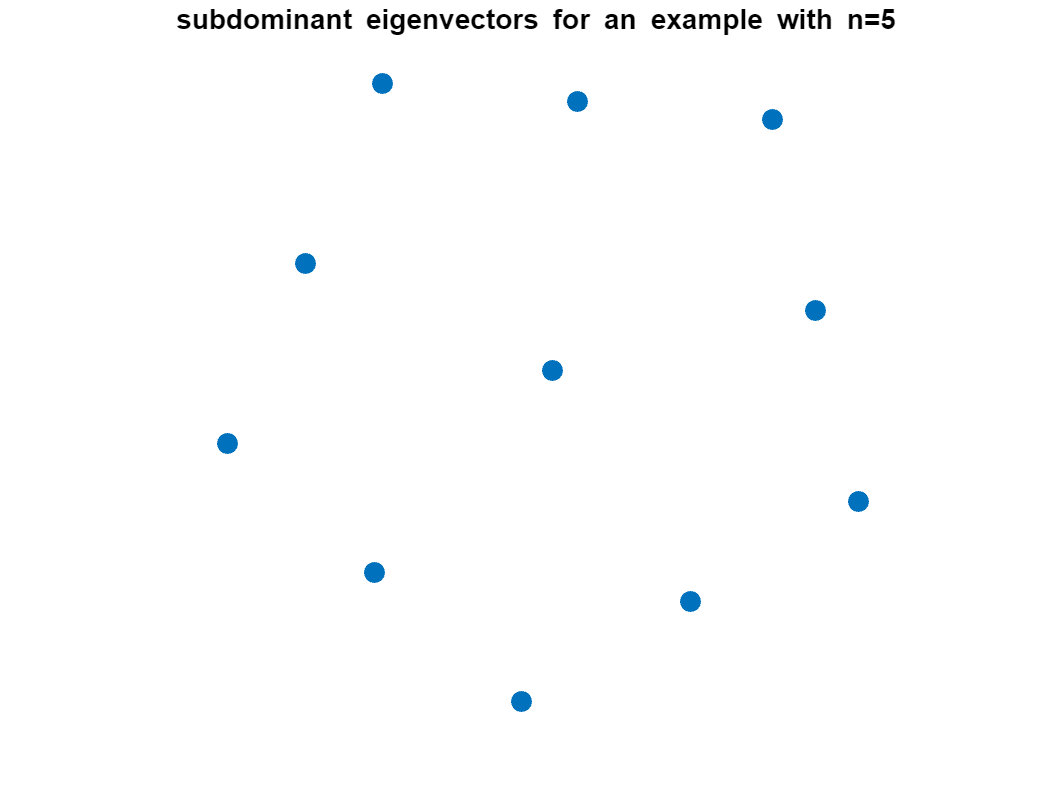

B=S-1/2*eye(length(S));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors for an example with n=5 \newline  ')

Multiplying the subdivision matrix by the eigenvectors results in:

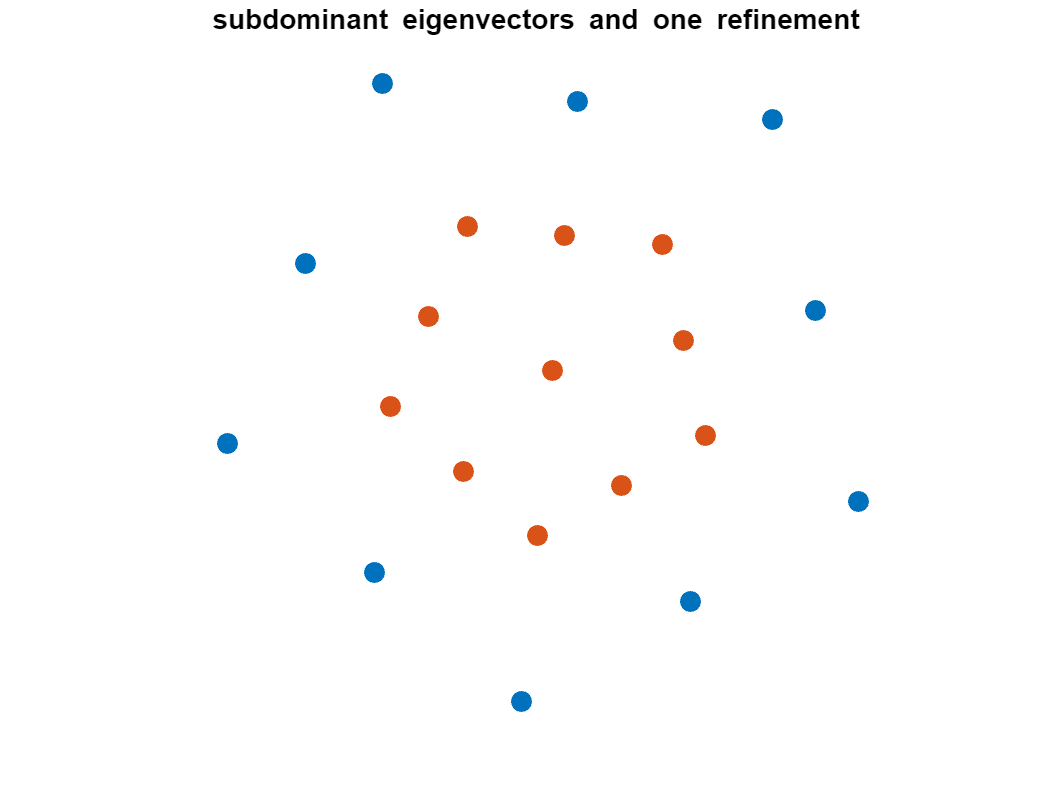

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off

title('subdominant eigenvectors and one refinement \newline  ')

V=S*V;
plot(V(:,1),V(:,2),'.r','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more:

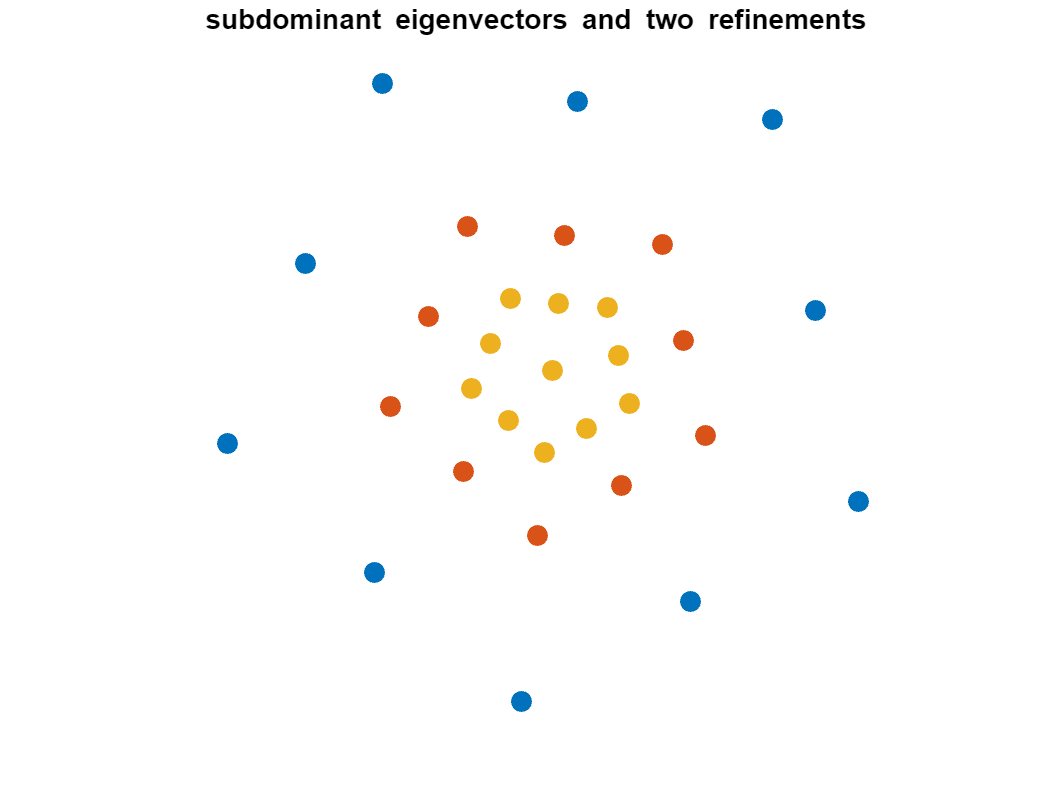

B=S-1/2*eye(length(S));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off

title('subdominant eigenvectors and two refinements \newline  ')

V=S*V;
plot(V(:,1),V(:,2),'.r','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=S*V;
plot(V(:,1),V(:,2),'.r','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

### 4.2 Bigger Structures

Larger matrices can be computed similarly. Using the follwing command we obtain the subdivision matrix. Its structure is:

SBig=computeBiCubicSubdivisionMatrixBig(5)

SBig =     0.6329         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0056    0.0678         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.2500    0.2500         0         0         0         0    0.2500    0.2500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

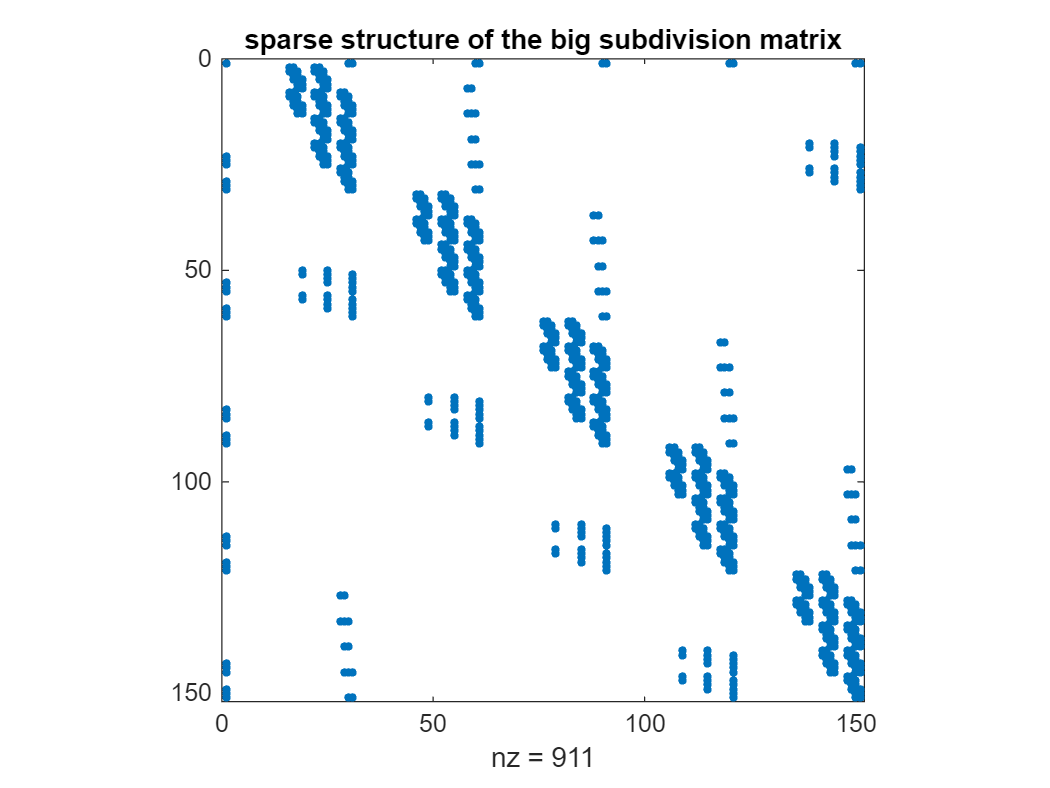

figure
spy(SBig);
hold on
title('sparse structure of the big subdivision matrix')

The six largest eigenvalues are:

sort(eig(SBig),'descend')

ans =    1.0000 + 0.0000i
   0.5000 + 0.0000i
   0.5000 + 0.0000i
   0.2985 + 0.0000i
   0.2985 + 0.0000i
   0.2500 + 0.0000i
   0.1250 + 0.0000i
   0.1250 + 0.0000i
   0.1250 + 0.0000i
   0.1250 + 0.0000i


The subdominant eigenvectors can be plotted as follows:

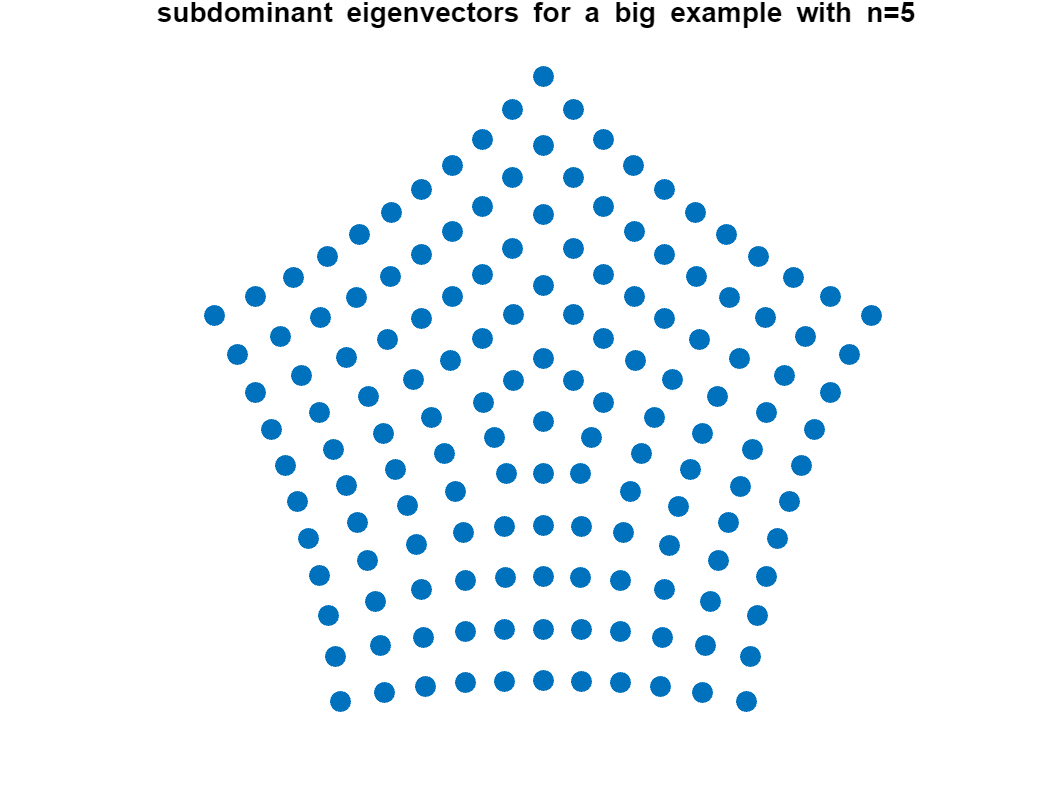

B=SBig-1/2*eye(length(SBig));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
title('subdominant eigenvectors for a big example with n=5 \newline  ')
axis equal
axis off

Multiplying the subdivision matrix by the eigenvectors results in:

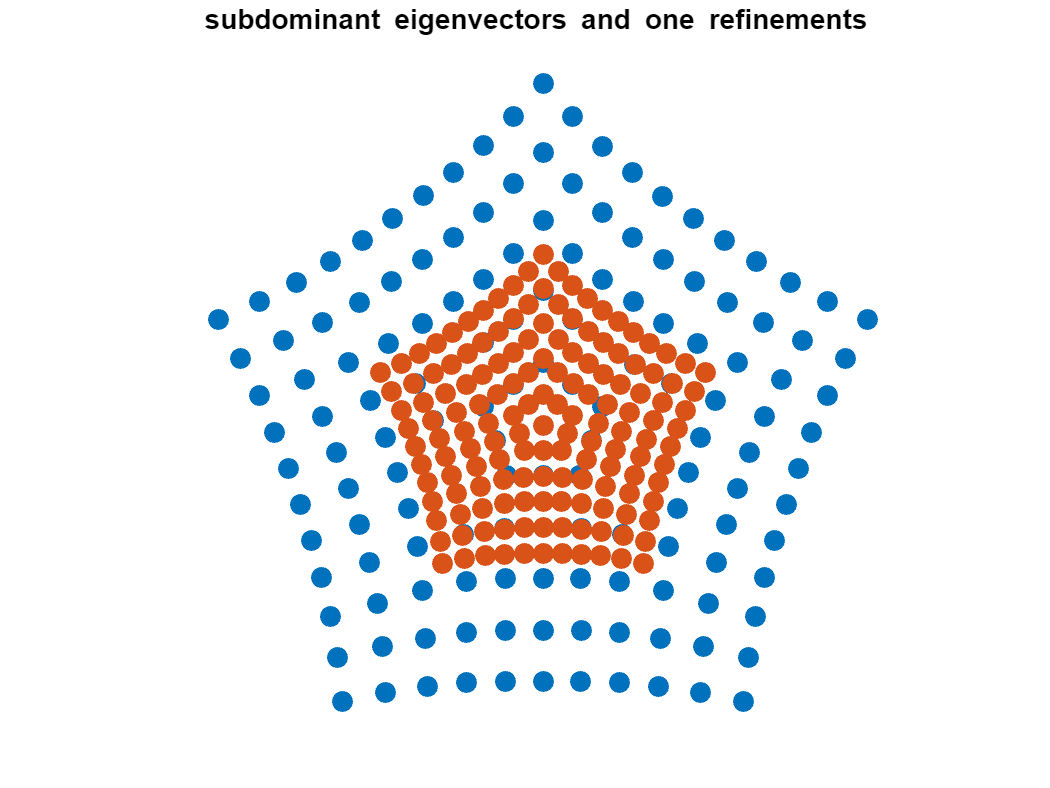

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off

V=SBig*V;

plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);
title('subdominant eigenvectors and one refinements \newline  ')

Once more:

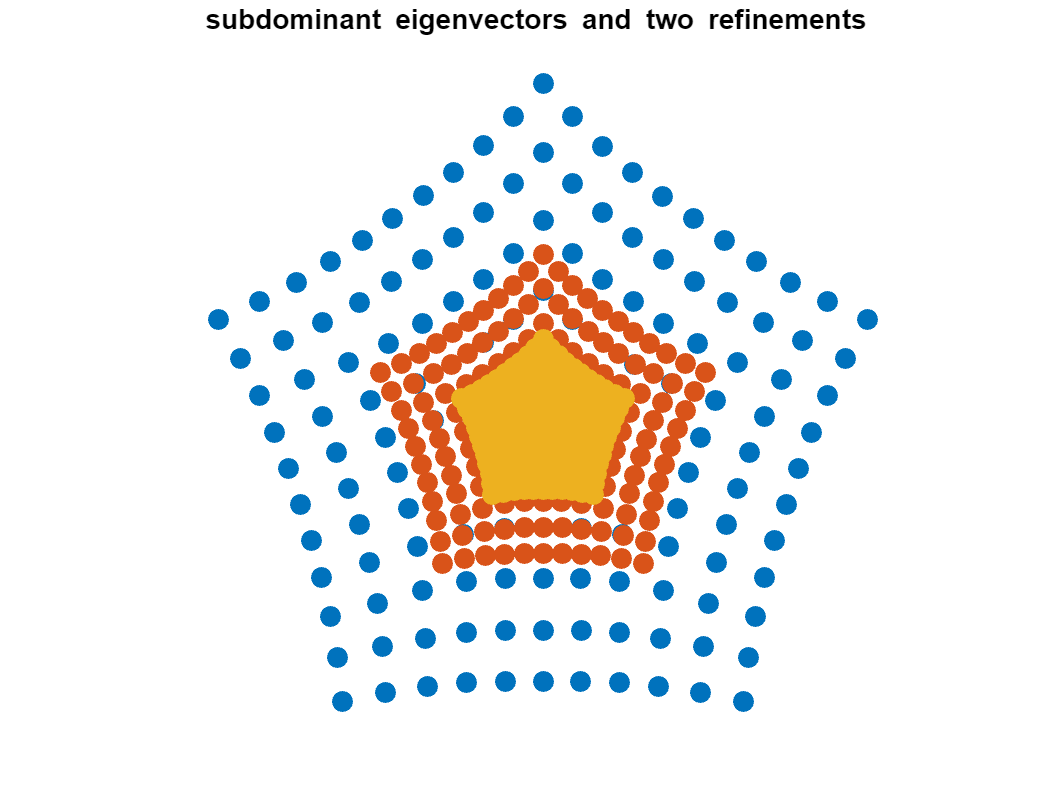

B=SBig-1/2*eye(length(SBig));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off

V=SBig*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

title('subdominant eigenvectors and two refinements \newline  ')

V=SBig*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

## 5 The Volume Case

We will now begin with the volume case. There are again two main files for this volume case:

computeTriCubicSubdivisionMatrix(Input,varargin)

computeTriCubicSubdivisionMatrixBig(Input,varargin)

The functions without the "Big" suffix compute subdivision matrices for the initial stages of subdivision. These refine a complex of cubes sharing a vertex into a smaller one. 

The functions with the "Big" suffix compute subdivision matrices for a larger area to support B-spline evaluation. Specifically, these functions refine a double shell into a smaller double shell of B-spline cubes.

### 5.1 Input

We will now look at the general input, which is the parameter "Input

For all two functions, this input represents the combinatorial structure of the dual central polytope of the central complex. There are three possible data formats. The first is the adjacency matrix. For the regular case, an example would be: 

A=computePrismFaceMatrix(4);
A=FaceToAdjacencyMatrix(A)

A =      0     1     0     1     1     0     0     0
     1     0     1     0     0     1     0     0
     0     1     0     1     0     0     1     0
     1     0     1     0     0     0     0     1
     1     0     0     0     0     1     0     1
     0     1     0     0     1     0     1     0
     0     0     1     0     0     1     0     1
     0     0     0     1     1     0     1     0


Alternatively, the input can be a list of faces. Each row of this list matrix represents a face, and each entry is a vertex of that face. For the regular case, an example would be:

F=computeFaceMatrix(A,false)

F =      1     2     3     4
     1     2     6     5
     1     4     8     5
     2     3     7     6
     3     4     8     7
     5     6     7     8


The third option is a list of edges. For the regular case, this would look like:

G=graph(A);
E=G.Edges.EndNodes

E =      1     2
     1     4
     1     5
     2     3
     2     6
     3     4
     3     7
     4     8
     5     6
     5     8


### 5.2 Output: Initial Elements

Before we look at the optional input parameters, let''s review the output. For the functions without the "Big" suffix, the first output is simply the subdivision matrix, which refines the complex of cubes sharing a vertex into a smaller complex of cubes. 

For the regular case, we obtain 

S=computeTriCubicSubdivisionMatrix(A)

S =     0.1250         0         0         0         0         0         0         0    0.1250    0.1250    0.1250         0         0         0         0         0         0         0         0         0    0.1250    0.1250    0.1250         0         0         0    0.1250
         0    0.1250         0         0         0         0         0         0    0.1250         0         0    0.1250    0.1250         0         0         0         0         0         0         0    0.1250    0.1250         0    0.1250         0         0    0.1250
         0         0    0.1250         0         0         0         0         0         0         0         0    0.1250         0    0.1250    0.1250         0         0         0         0         0    0.1250         0         0    0.1250    0.1250         0    0.1250
         0         0         0    0.1250         0         0         0         0         0    0.1250         0         0         0    0.1250         0    0.1250         0         0   

Next, we will illustrate the algorithms with a more complex example. From now on, we will use the face matrix as input.

F=[1,2,3,4,5;...
1,2,7,8,6;...
2,3,7,0,0;...
3,4,8,7,0;...
4,5,6,8,0;...
5,1,6,0,0]

F =      1     2     3     4     5
     1     2     7     8     6
     2     3     7     0     0
     3     4     8     7     0
     4     5     6     8     0
     5     1     6     0     0


For the following command we obtain the subdivision matrix:

S=computeTriCubicSubdivisionMatrix(F)

S =     0.1196         0         0         0         0         0         0         0    0.2371    0.0861    0.0861         0         0         0         0         0         0         0         0         0    0.1259         0         0         0    0.1136    0.1136    0.1179
         0    0.1196         0         0         0         0         0         0    0.2371         0         0    0.0861    0.0861         0         0         0         0         0         0         0         0    0.1259         0         0    0.1136    0.1136    0.1179
         0         0    0.0311         0         0         0         0         0         0         0         0    0.1082         0    0.2072    0.0289         0         0         0         0         0         0    0.1663    0.1159         0    0.1713         0    0.1712
         0         0         0    0.2349         0         0         0         0         0         0         0         0         0    0.1599         0    0.1599    0.0814         0   

The eigenvalues of this matrix are: 

D=sort(eig(S),'descend')

D =    1.0000 + 0.0000i
   0.5000 + 0.0000i
   0.5000 + 0.0000i
   0.5000 + 0.0000i
   0.3139 + 0.0000i
   0.2851 + 0.0000i
   0.2727 + 0.0000i
   0.2500 + 0.0000i
   0.2407 + 0.0000i
   0.2111 + 0.0000i


The subdominant eigenvectors can be plotted as follows:

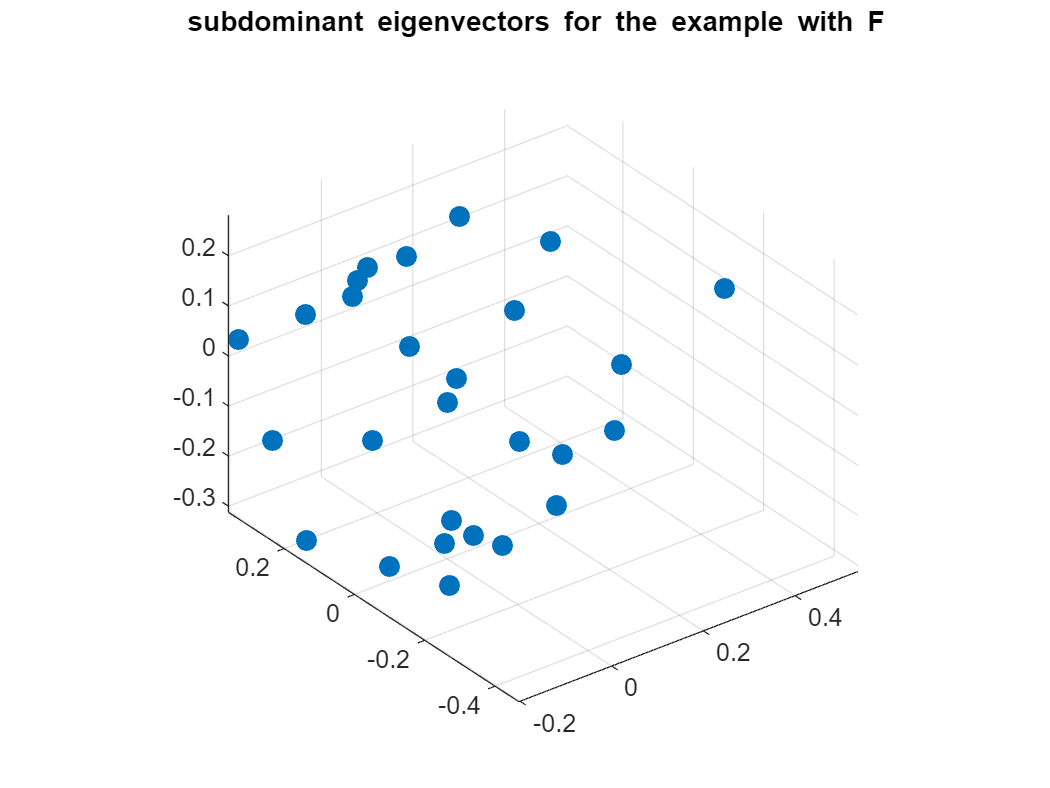

B=S-1/2*eye(length(S));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
grid on
title('subdominant eigenvectors for the example with F \newline  ')

Multiplying the subdivision matrix by the eigenvectors results in: 

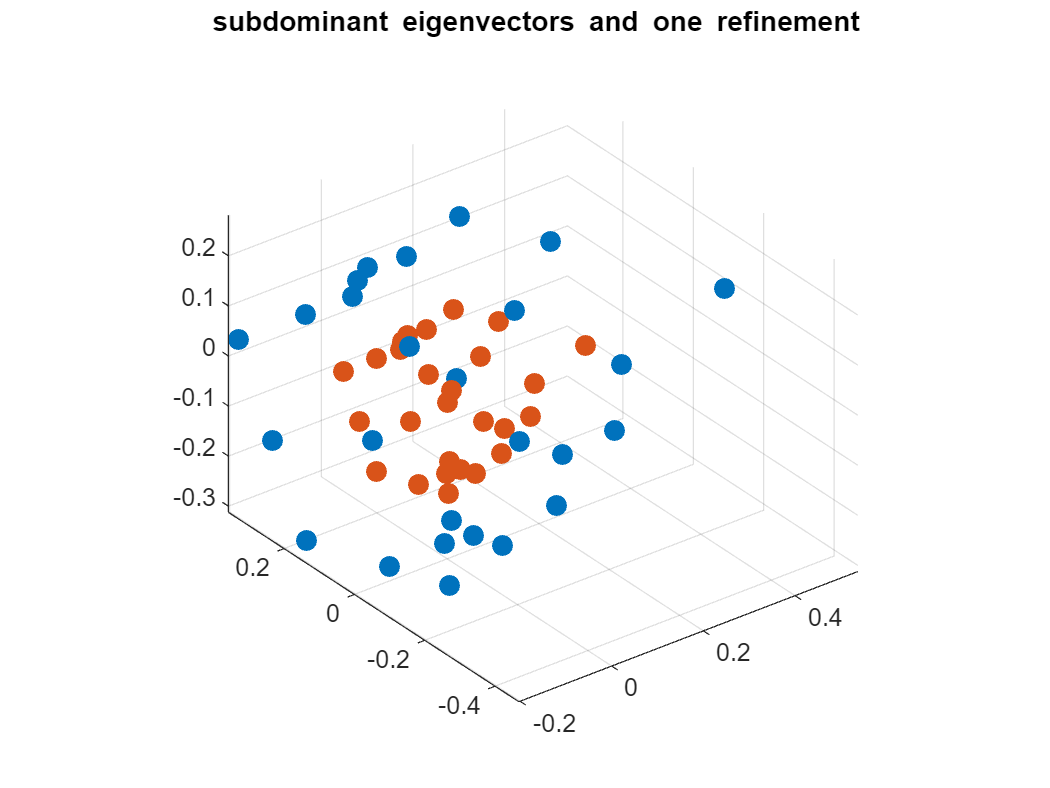

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
grid on
title('subdominant eigenvectors and one refinement \newline  ')

V=S*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more:

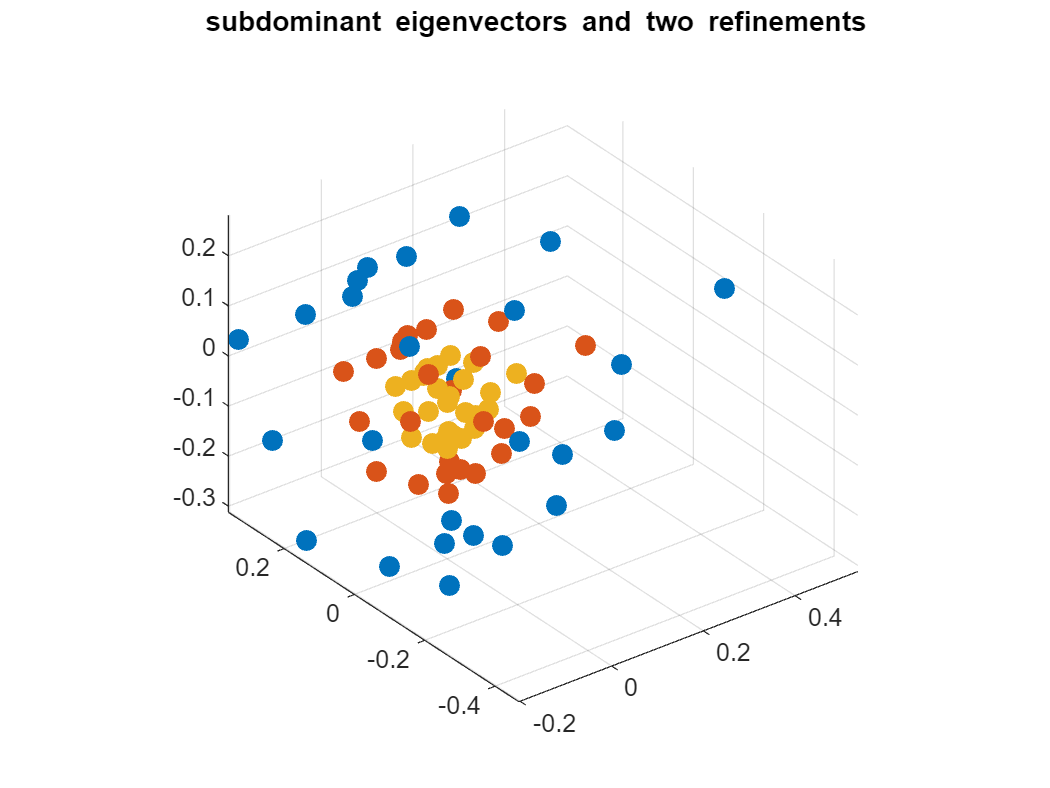

B=S-1/2*eye(length(S));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
grid on
title('subdominant eigenvectors and two refinements \newline  ')

V=S*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=S*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

### 5.3 Output: Bigger Structures

The larger matrices are quite similar. Using the following command 

F=[1,2,3,4,5;...
1,2,7,8,6;...
2,3,7,0,0;...
3,4,8,7,0;...
4,5,6,8,0;...
5,1,6,0,0]

F =      1     2     3     4     5
     1     2     7     8     6
     2     3     7     0     0
     3     4     8     7     0
     4     5     6     8     0
     5     1     6     0     0


computeTriCubicSubdivisionMatrixBig(F)

ans =     0.3681         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.3162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

we obtain the subdivision matrix with the structure: 

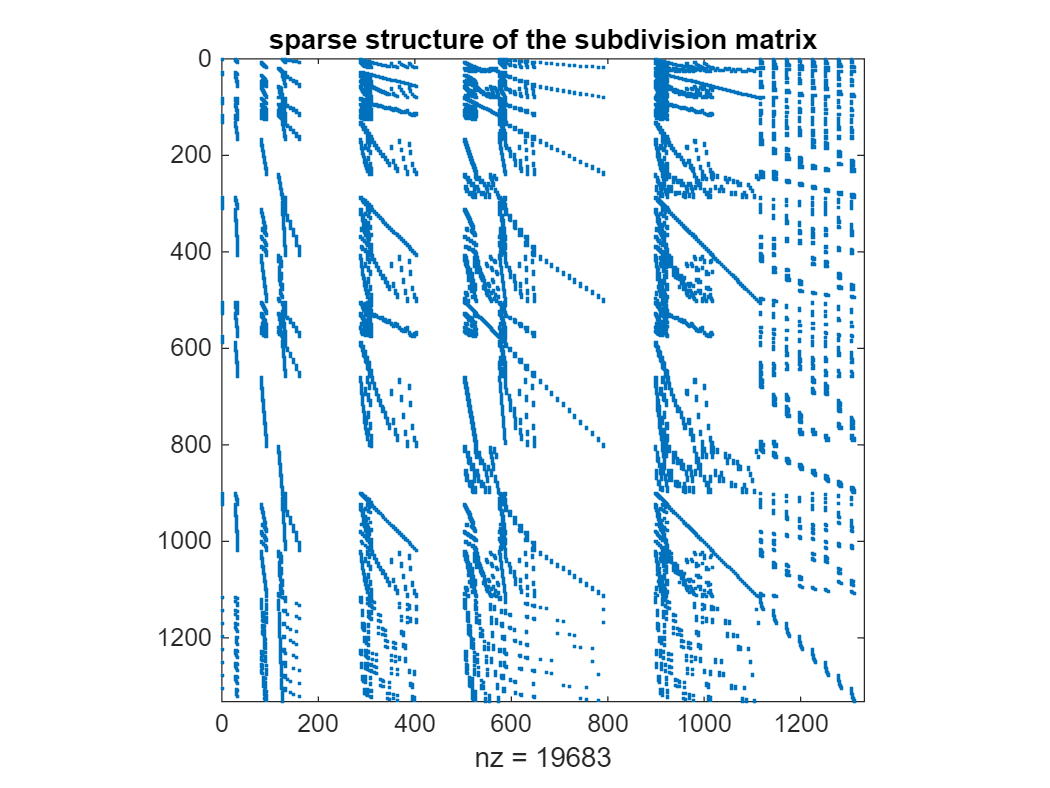

SBig=computeTriCubicSubdivisionMatrixBig(F);

figure
spy(SBig);
title('sparse structure of the subdivision matrix')

he eigenvalues of this matrix are: 

D=sort(eig(SBig),'descend')

D =    1.0000 + 0.0000i
   0.5000 + 0.0000i
   0.5000 + 0.0000i
   0.5000 + 0.0000i
   0.3139 + 0.0000i
   0.2851 + 0.0000i
   0.2727 + 0.0000i
   0.2500 + 0.0000i
   0.2407 + 0.0000i
   0.2111 + 0.0000i


The subdominant eigenvectors can be plotted as follows:

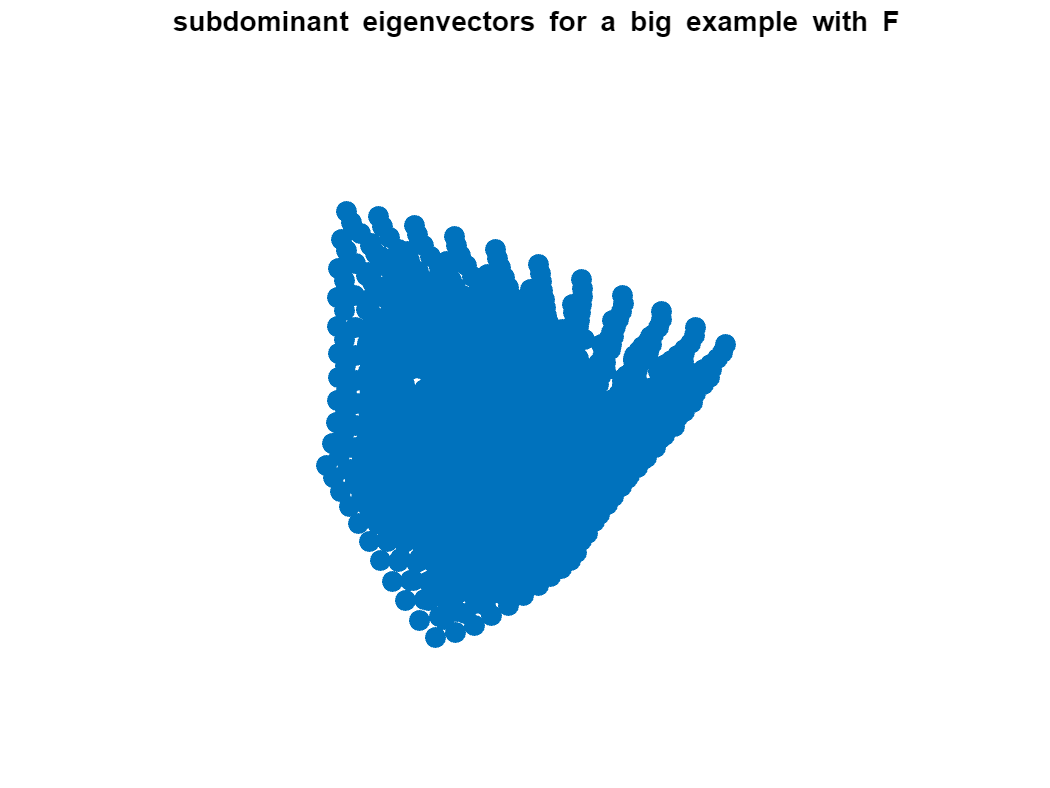

B=SBig-1/2*eye(length(SBig));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors for a big example with F \newline  ')

Multiplying the subdivision matrix by the eigenvectors results in:

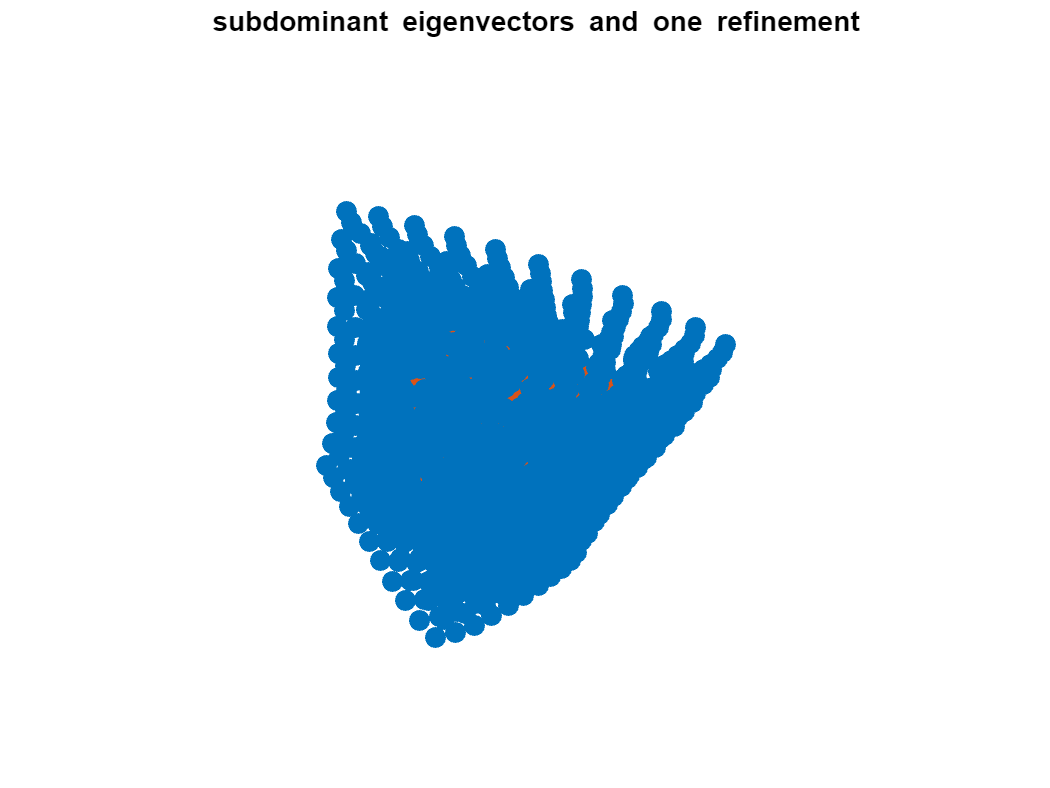

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and one refinement \newline  ')

V=SBig*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more:

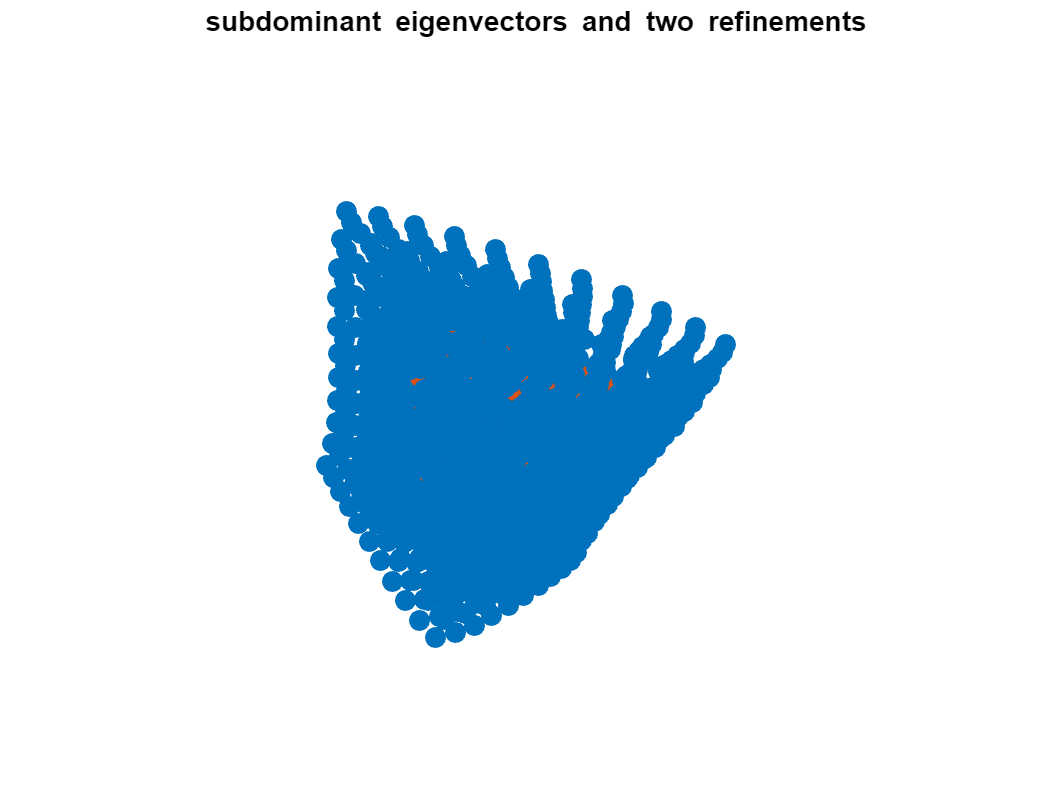

B=SBig-1/2*eye(length(SBig));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and two refinements \newline  ')

V=SBig*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=SBig*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

### 5.4 Output: Lattice

For both functions, there is an additional output parameter called "Lattice". This parameter encodes the structure of the control points or, more precisely, the underlying structure. Let n represent the number of control points in the structure. Each column of \"Lattice\" then has size n^2, since each column represents an adjacency matrix of a cube in this structure. The original adjacency matrices can be reconstructed using the command 

[S1Big,Lattice]=computeTriCubicSubdivisionMatrixBig(F);
k=length(S1Big);
full(reshape(Lattice(:,1),[k,k]))

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

The structure of the "Lattice" matrix for our "Big" example is

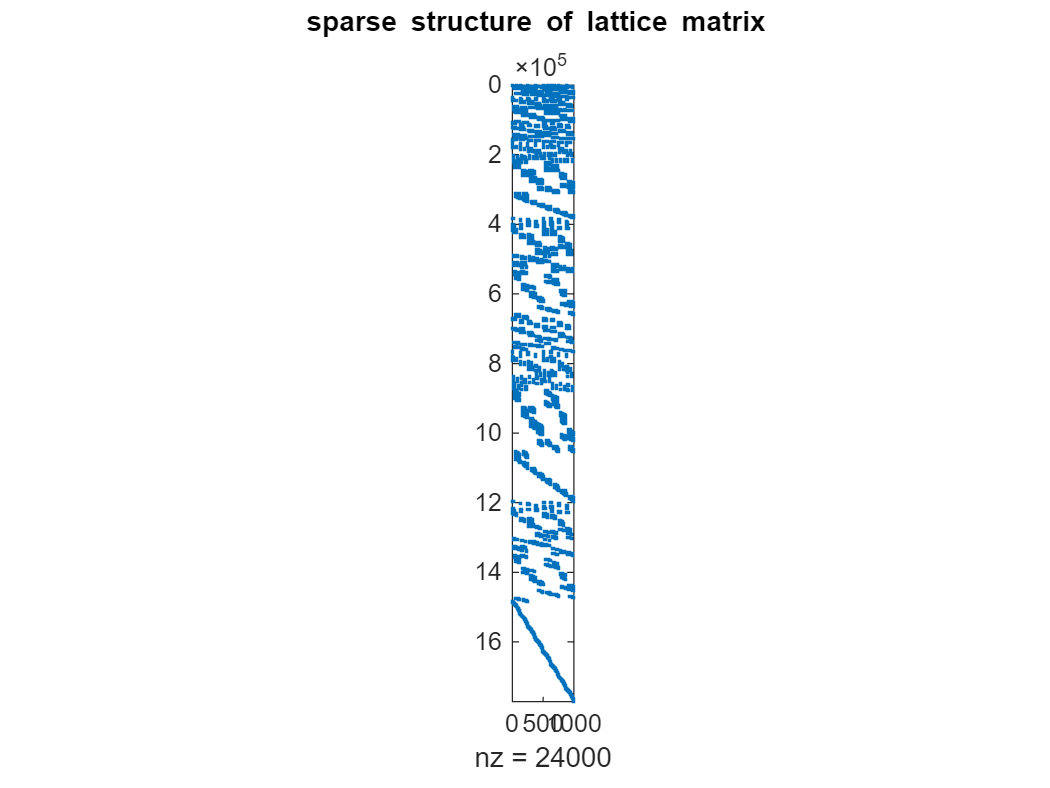

[S1Big,Lattice]=computeTriCubicSubdivisionMatrixBig(F);

figure
spy(Lattice)
title('sparse structure of lattice matrix \newline ')

### 5.5 Optional Commands

Now we will take a look at the additional input parameters.

The first additional input argument is 'Status'. If this parameter is included, the algorithm will display the status of the construction process. Using the following command we get:

%computeTriCubicSubdivisionMatrix(F,'Status');

(Remark: Usually the lines are cleared by the clc command. A realistic view of this optional input can be seen in the corresponding demo DemoCubic)

Similarly, for the "Big" function, using the following command we get

%computeTriCubicSubdivisionMatrixBig(F,'Status');

(Remark: Usually the lines are cleared by the clc command. A realistic view of this optional input can be seen in the corresponding demo DemoCubic)

The second additional input argument is 'PreventInputCheck' If this parameter is included, the algorithm will skip the check to ensure that the input represents a planar 3-connected graph. The command is

computeTriCubicSubdivisionMatrix(F,'PreventInputCheck');

The third additional input argument is 'Tolerance'. This parameter allows you to manually set the tolerance for the numerical parts of the algorithm. The default value is 10^(-13). The command is 

computeTriCubicSubdivisionMatrix(F,'Tolerance',10^(-8));

You can also manually set the maximum number of iterations for the numerical parts using the 'MaxIterations' parameter. The default value is 100. To change it, use the command 

computeTriCubicSubdivisionMatrix(F,'MaxIterations',50);

Of course, these options also apply to the functions with the "Big" suffix.

Another input parameter is 'Visualization'. With this parameter, various graphics are generated during the construction process. Use the command 

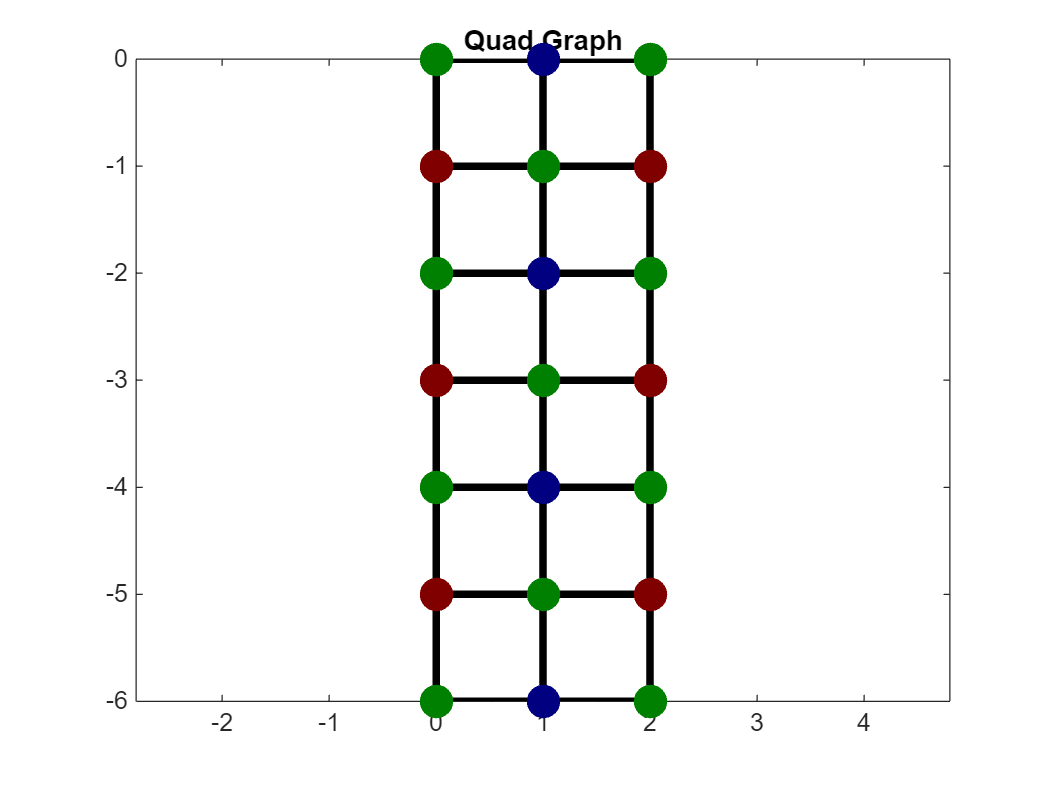

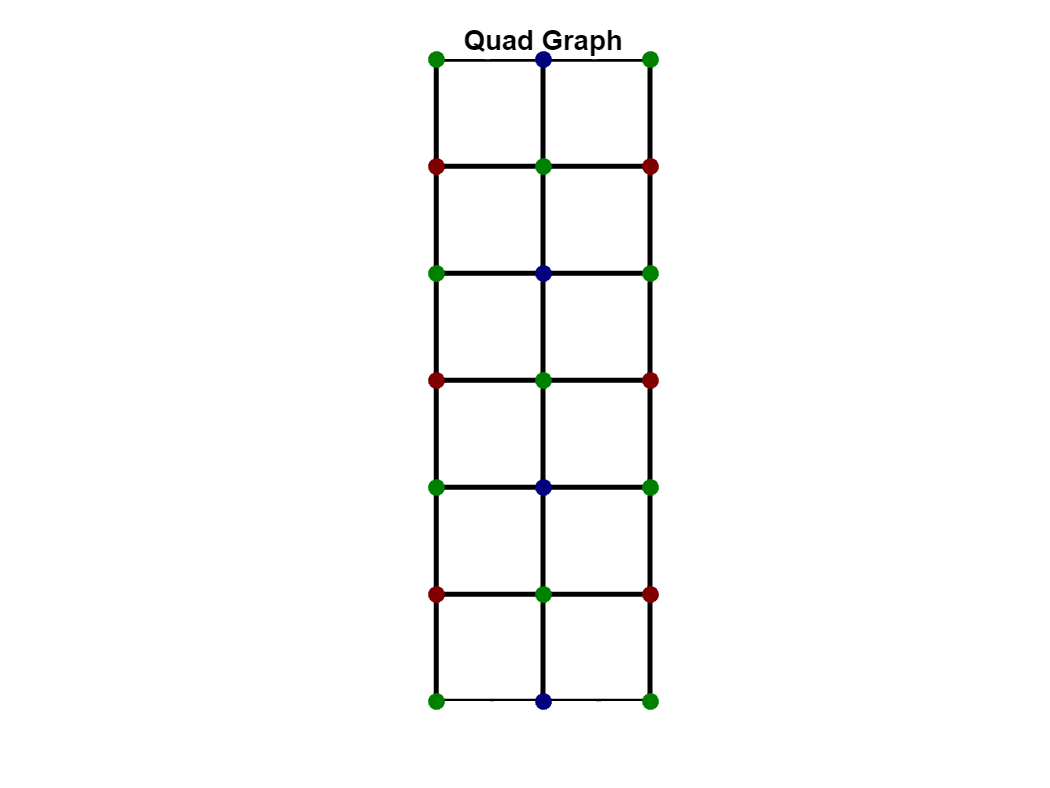

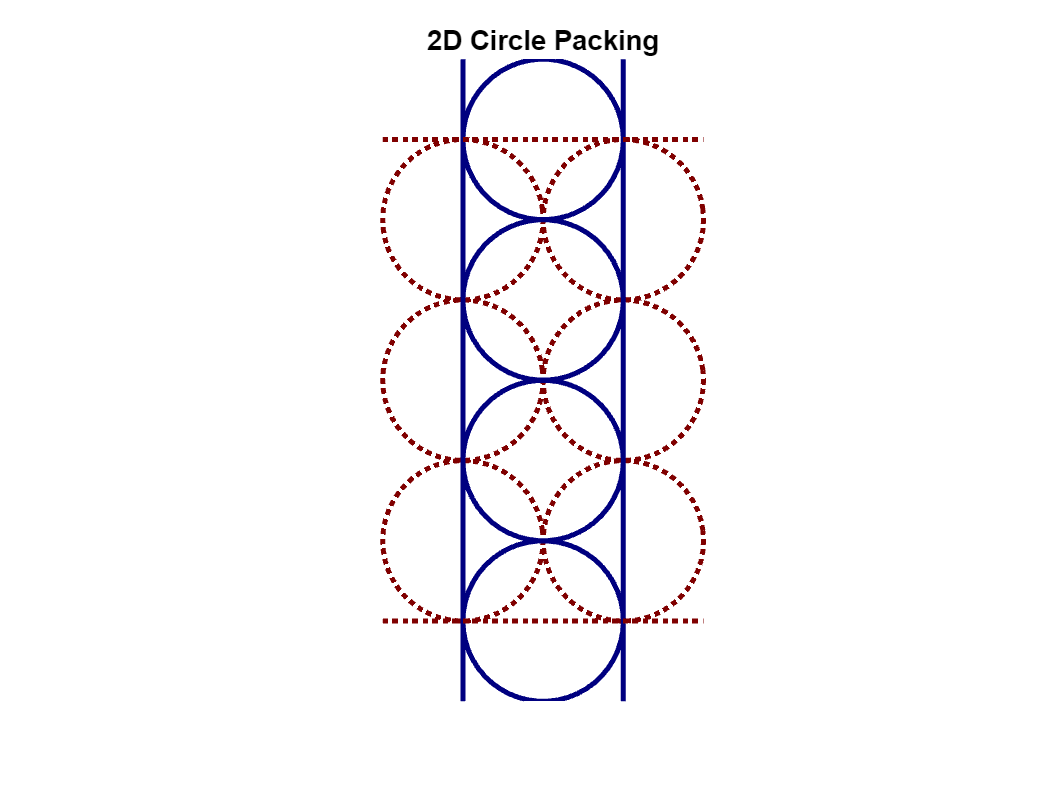

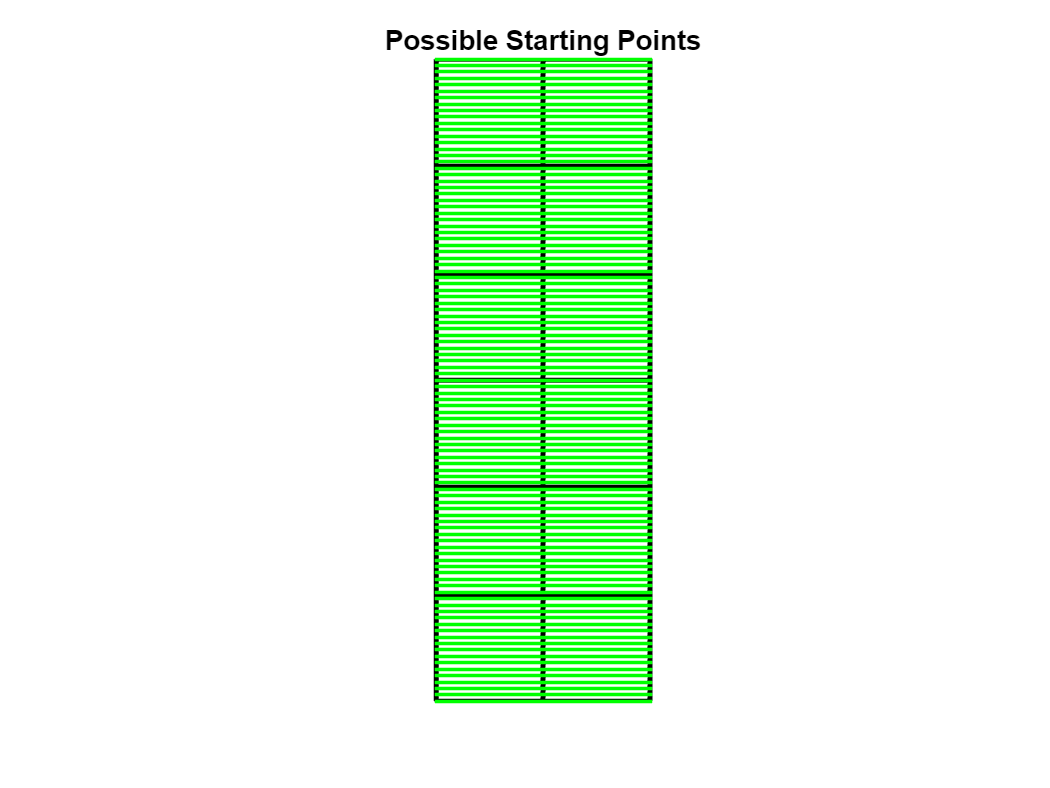

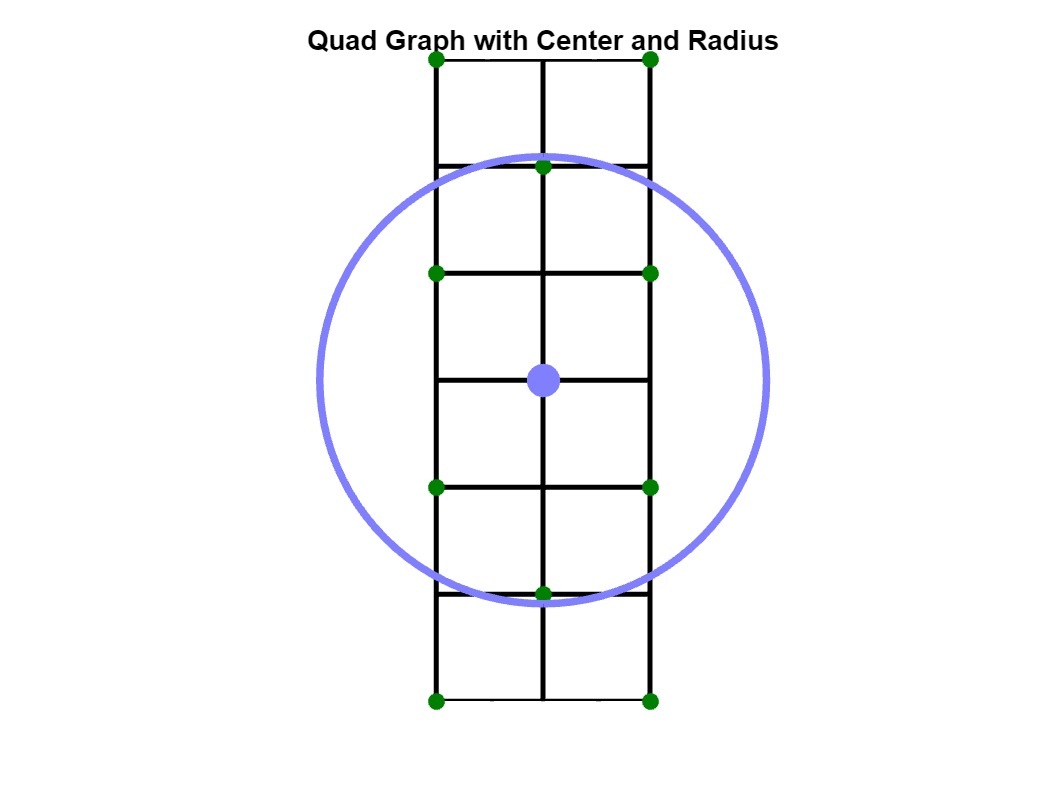

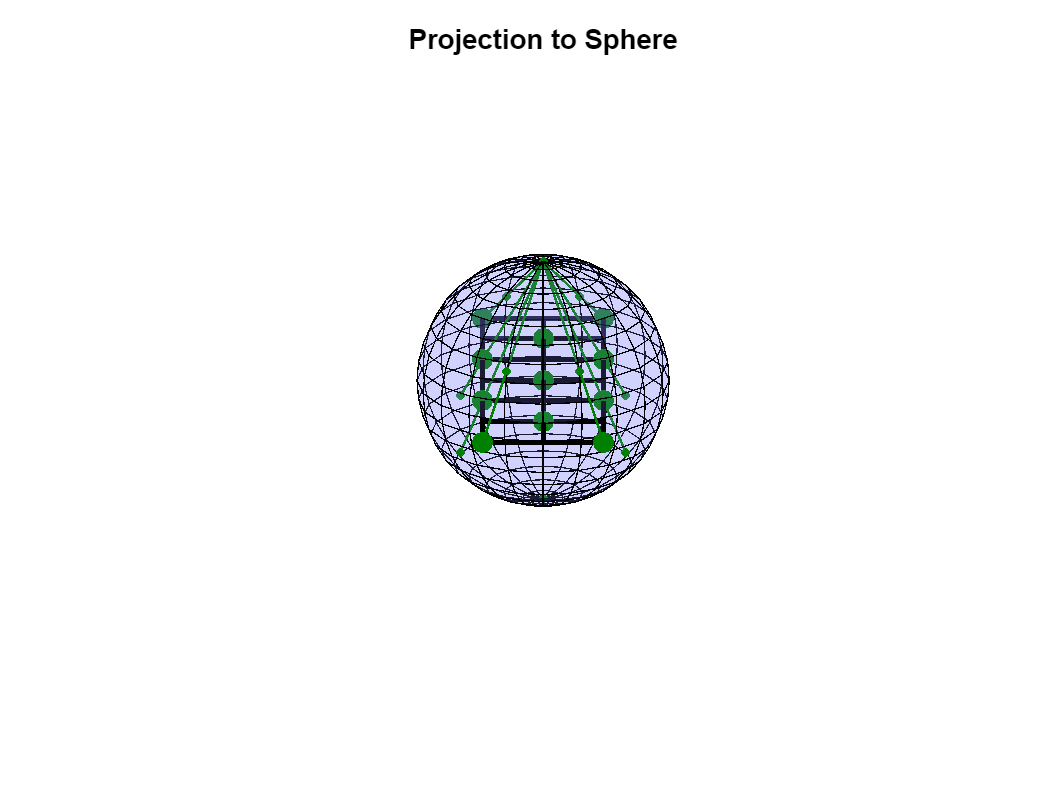

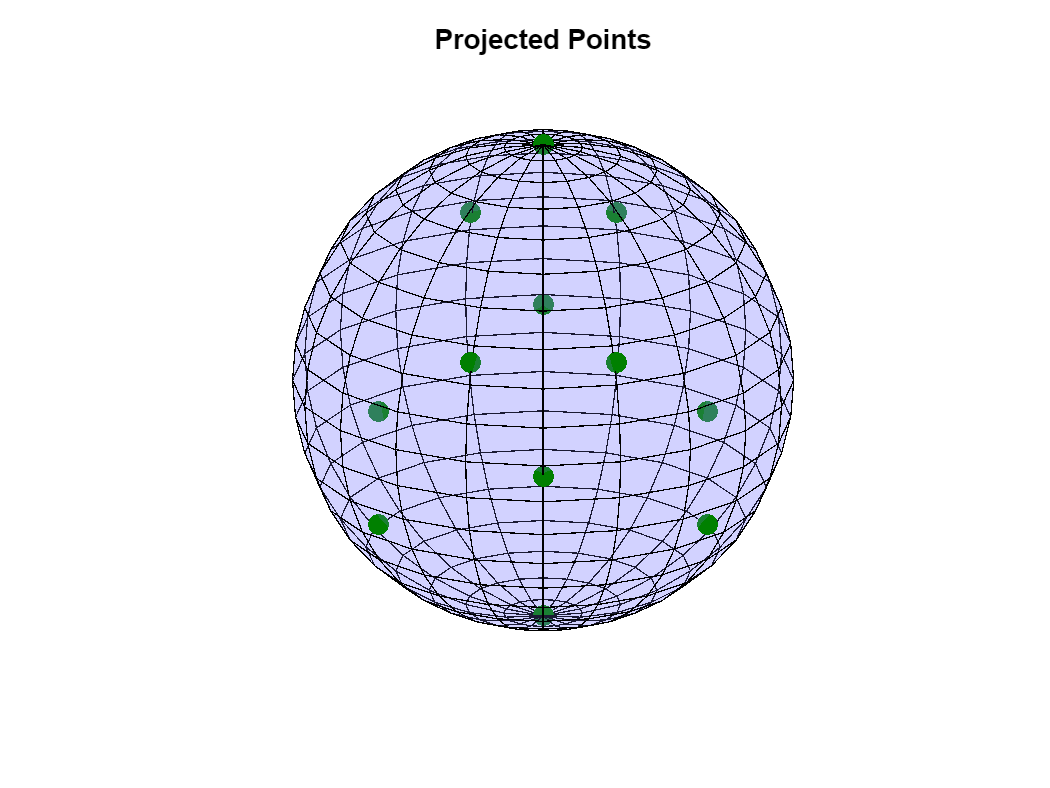

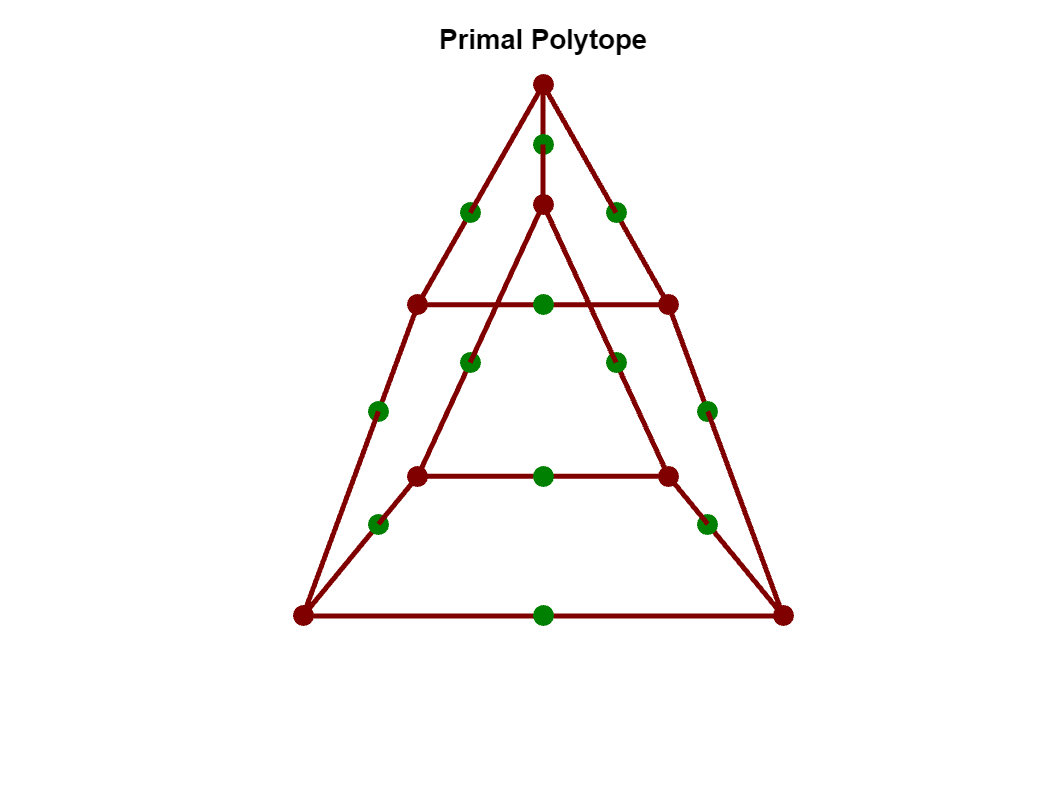

figure
computeTriCubicSubdivisionMatrix(F,'Visualization');

A total of 14 figures are created. The background and explanations for these figures can be found in the corresponding dissertation. 

For the functions with the "Big" suffix, only one figure is created. It can be generated with the command

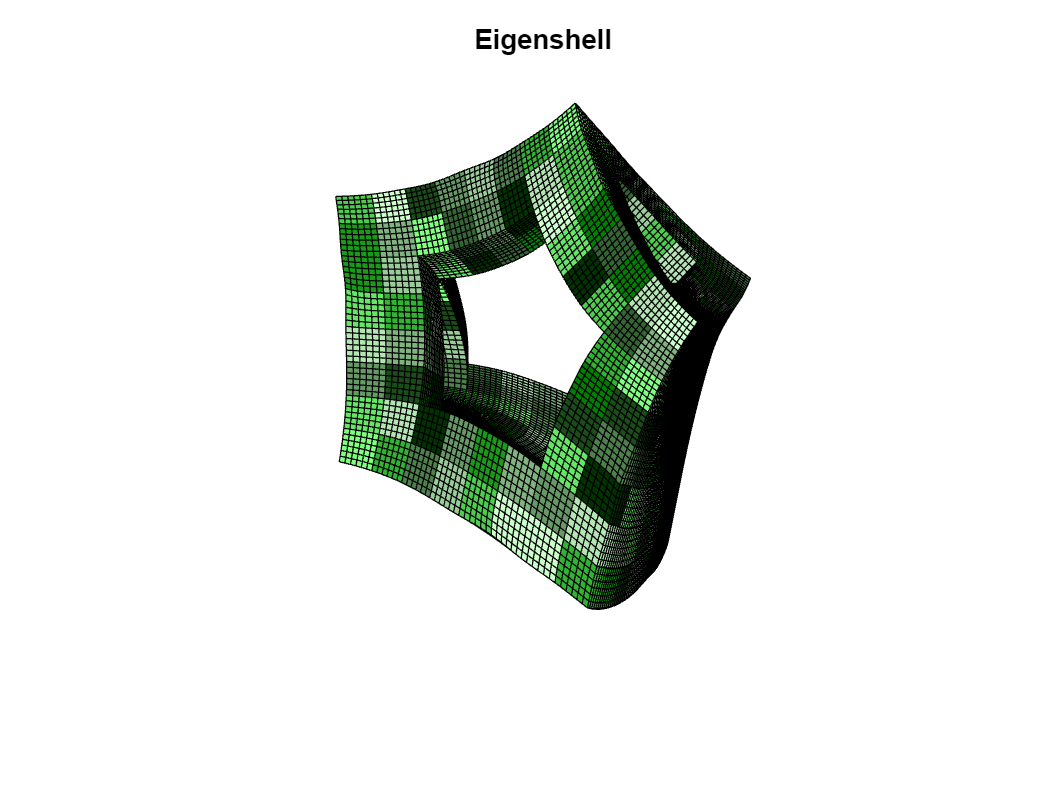

figure
computeTriCubicSubdivisionMatrixBig(F,'Visualization');

These figures can be manipulated in different ways. For example, with the command 

%computeTriCubicSubdivisionMatrix(F,'Visualization','DrawAfterXKites',4);

the initial iterative figure will display faster as four kites are drawn in one step.

Using the command 

%computeTriCubicSubdivisionMatrix(F,'Visualization','View',[26,5]);

the viewing angle of the figures can be adjusted.

And with the command 

%computeTriCubicSubdivisionMatrix(F,'Visualization','PrintImages','Test','.png')

the graphics are exported to .png files with the prefix 'Test' and the suffix '.png'.

## 6 Quality-of-Life Functions  

There are also two quality-of-life functions.

### 6.1 Plot Function

The first one is a plot function. We start with an example using the following commands

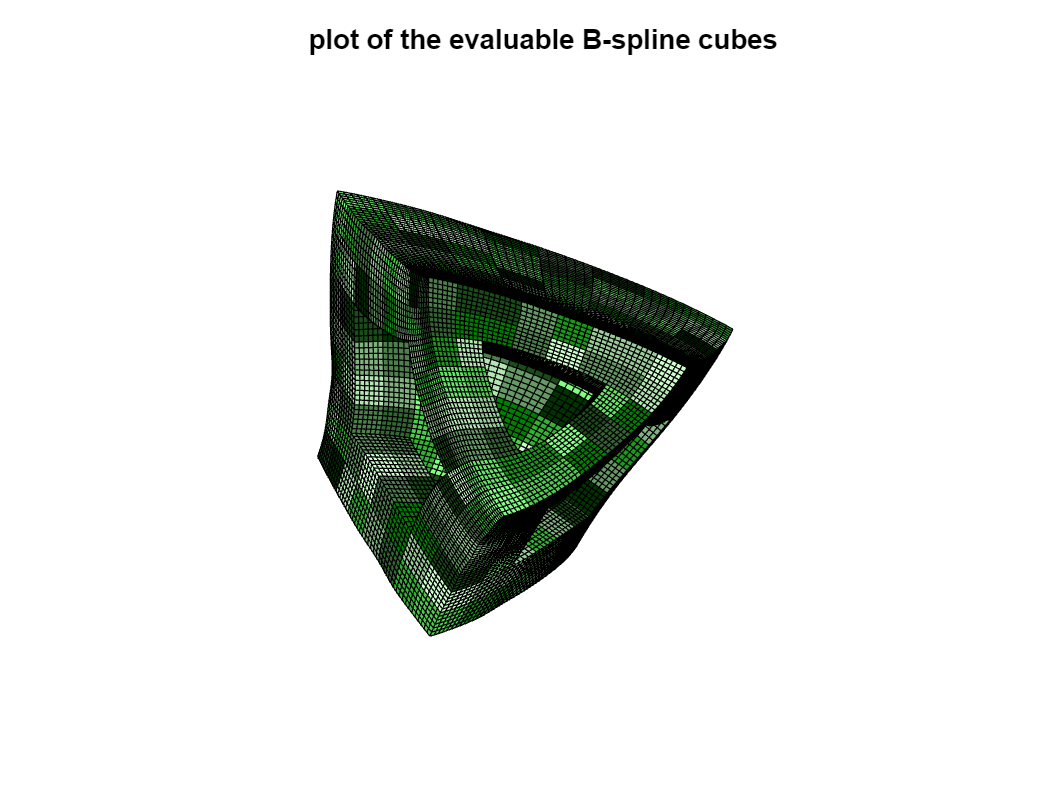

[S,Lattice]=computeTriCubicSubdivisionMatrixBig(F);
B=S-1/2*eye(length(S));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));
Controlpoints=V;

figure
plotTriCubicBSplineLattice(Controlpoints,Lattice)
title('plot of the evaluable B-spline cubes')

The plot command has two optional input parameters. The first one is 'PointsPerCube'. This parameter allows you to specify how many points each cube should be evaluated in each direction. Using the following command we get: 

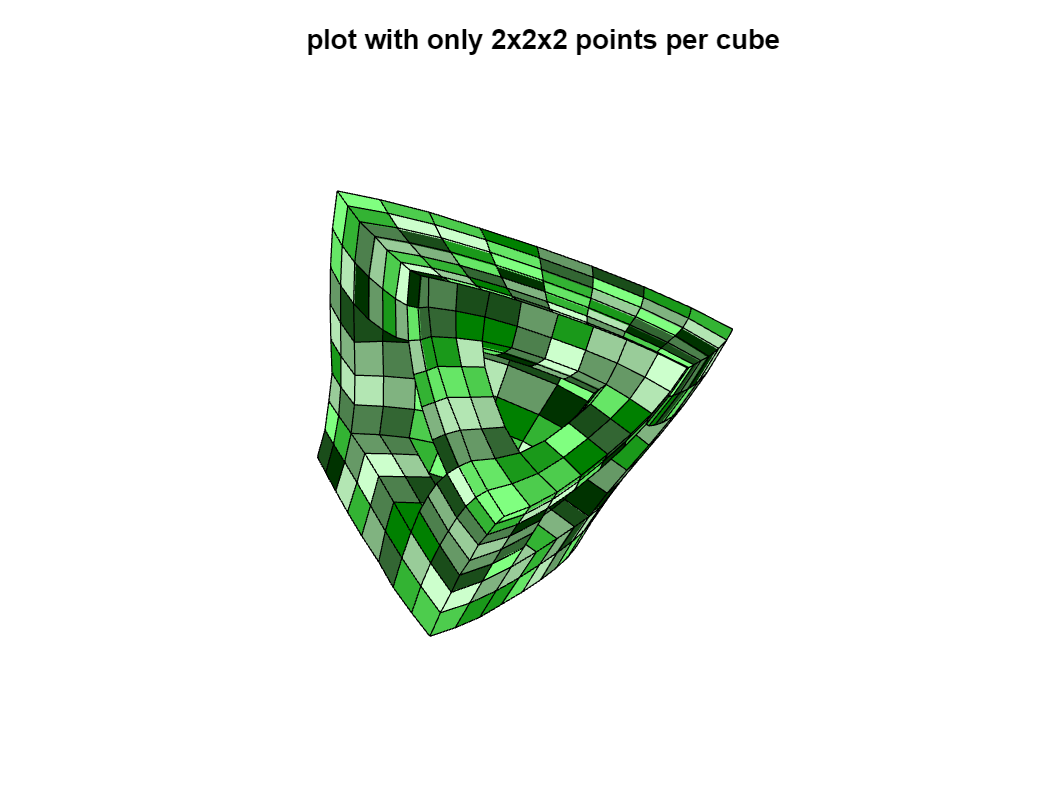

figure
plotTriCubicBSplineLattice(Controlpoints,Lattice,'PointsPerCube',2)

title('plot with only 2x2x2 points per cube')

The second optional parameter is 'ColorTable', which allows you to adjust the colors of the cubes. For example, we define:

ColorTable=[0.8,1,0.8;...  %1
            0.7,0.9,0.7;...%2
            0.6,0.8,0.6;...%3
            0.5,0.7,0.5;...%4
            0.4,0.6,0.4;...%5
            0.3,0.5,0.3;...%6
            0.2,0.4,0.2;...%7
            0.1,0.3,0.1;...%8
            0.0,0.2,0.0;...%9
            0,1/2,0;...    %10
            0.5,1,0.5;...  %11
            0.4,0.9,0.4;...%12
            0.3,0.8,0.3;...%13
            0.2,0.7,0.2;...%14
            0.1,0.6,0.1;...%15
            ];

CT=[ColorTable(:,[2,1,3])]

CT =     1.0000    0.8000    0.8000
    0.9000    0.7000    0.7000
    0.8000    0.6000    0.6000
    0.7000    0.5000    0.5000
    0.6000    0.4000    0.4000
    0.5000    0.3000    0.3000
    0.4000    0.2000    0.2000
    0.3000    0.1000    0.1000
    0.2000         0         0
    0.5000         0         0


Using the following command we get:

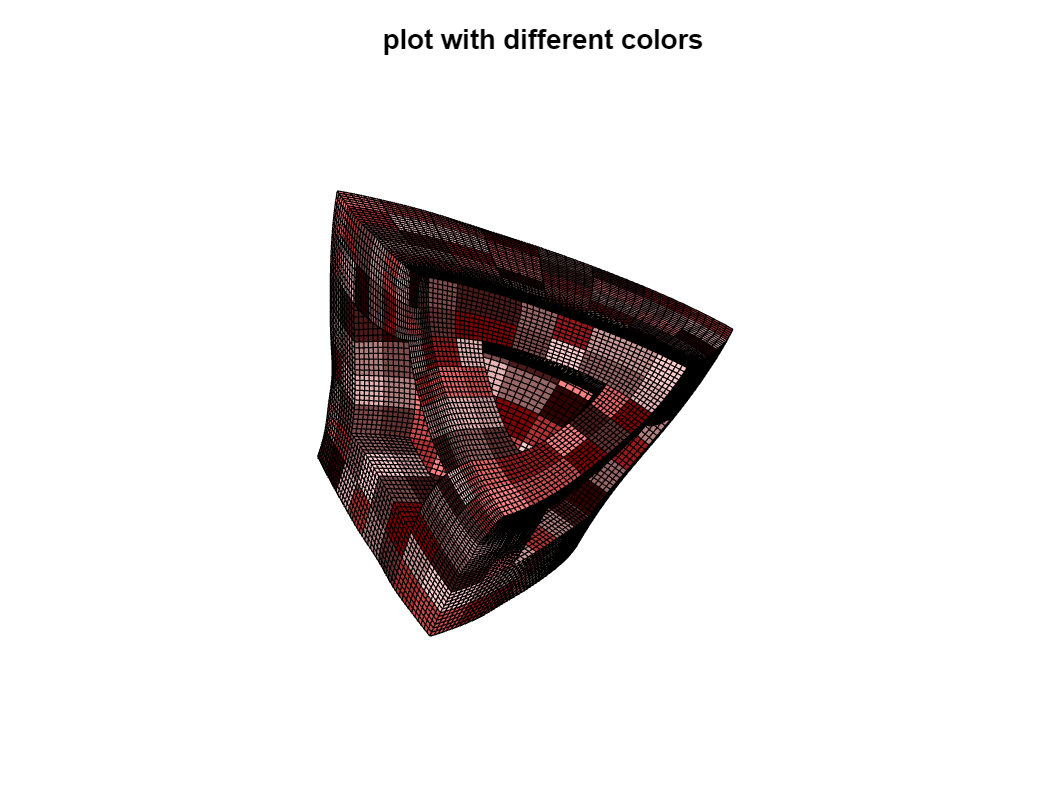

figure
plotTriCubicBSplineLattice(Controlpoints,Lattice,'ColorTable',CT)
title('plot with different colors')

### 6.2 Uniform Refinement

The second quality-of-life function is  uniform refinement. This function takes a matrix of control points and a lattice matrix and refines the entire structure uniformly. The available function is: 

RefineTriCubicLatticeUniform(Controlpoints,Lattice)

The output of these functions is a refined matrix of control points and the updated lattice matrix. A simple example is as follows:

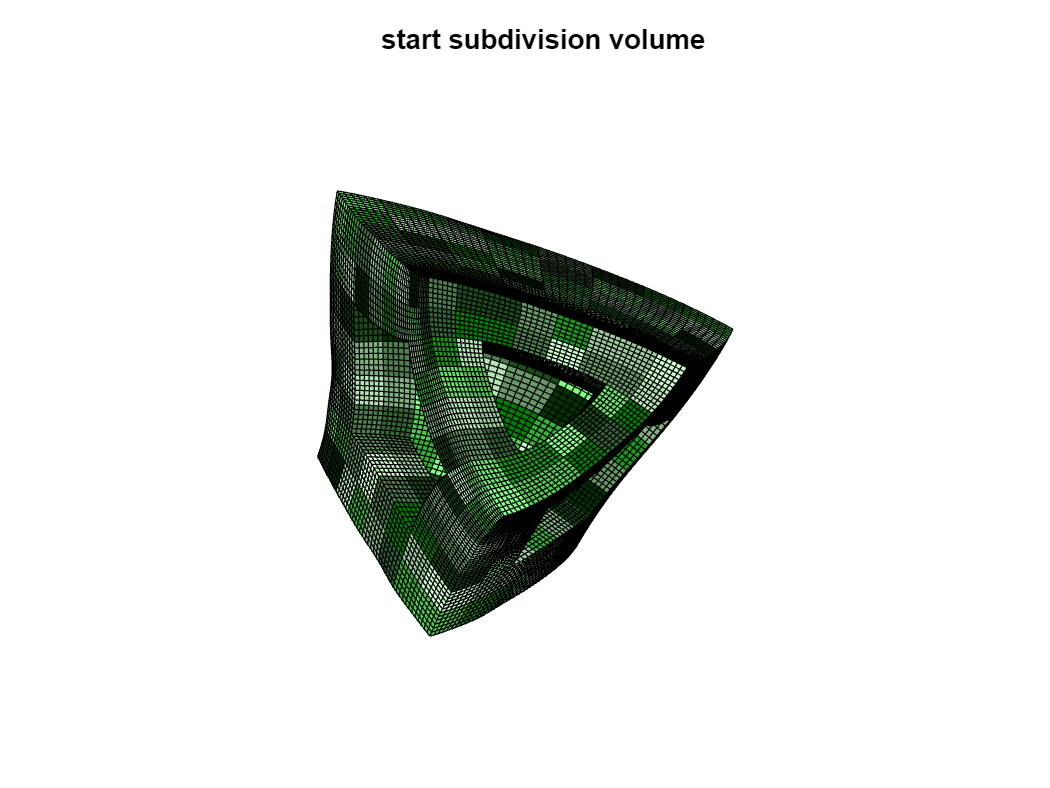

[S,Lattice]=computeTriCubicSubdivisionMatrixBig(F);
B=S-1/2*eye(length(S));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));
Controlpoints=V;
plotTriCubicBSplineLattice(Controlpoints,Lattice);
[Controlpoints,Lattice]=RefineTriCubicLatticeUniform(Controlpoints,Lattice);
title('start subdivision volume')

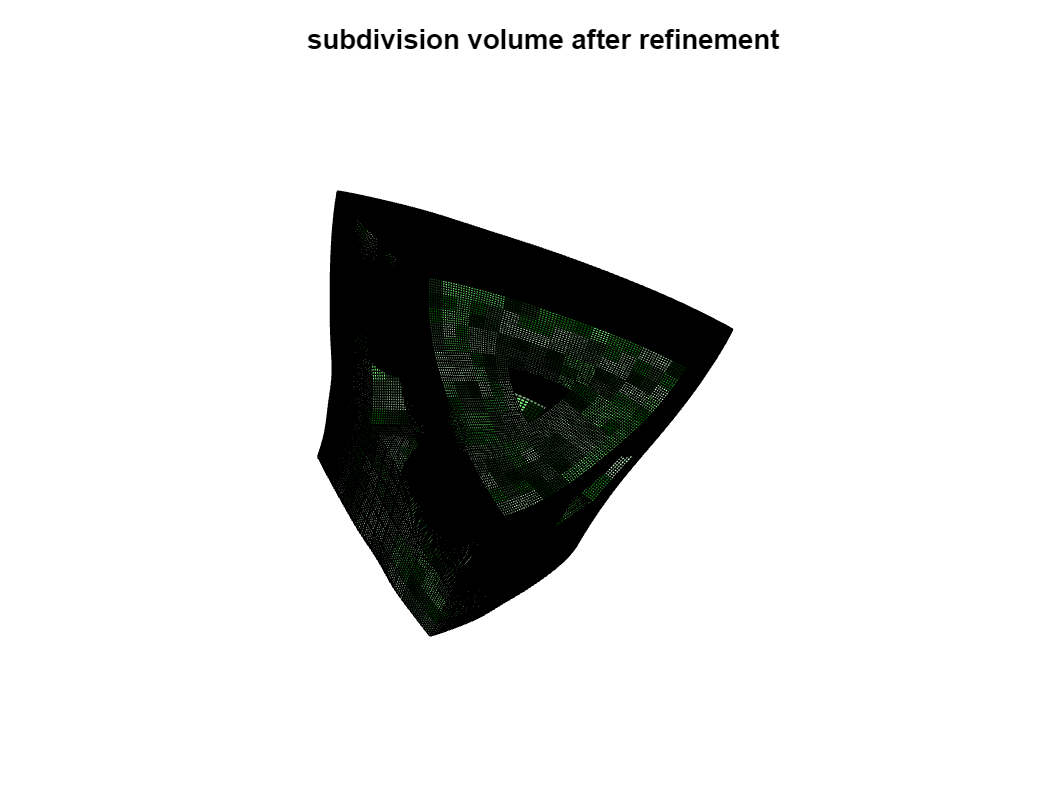

figure
plotTriCubicBSplineLattice(Controlpoints,Lattice);
title('subdivision volume after refinement')

This function can also handle lattices containing more than one irregular volume. Here is an (rather complex) example:

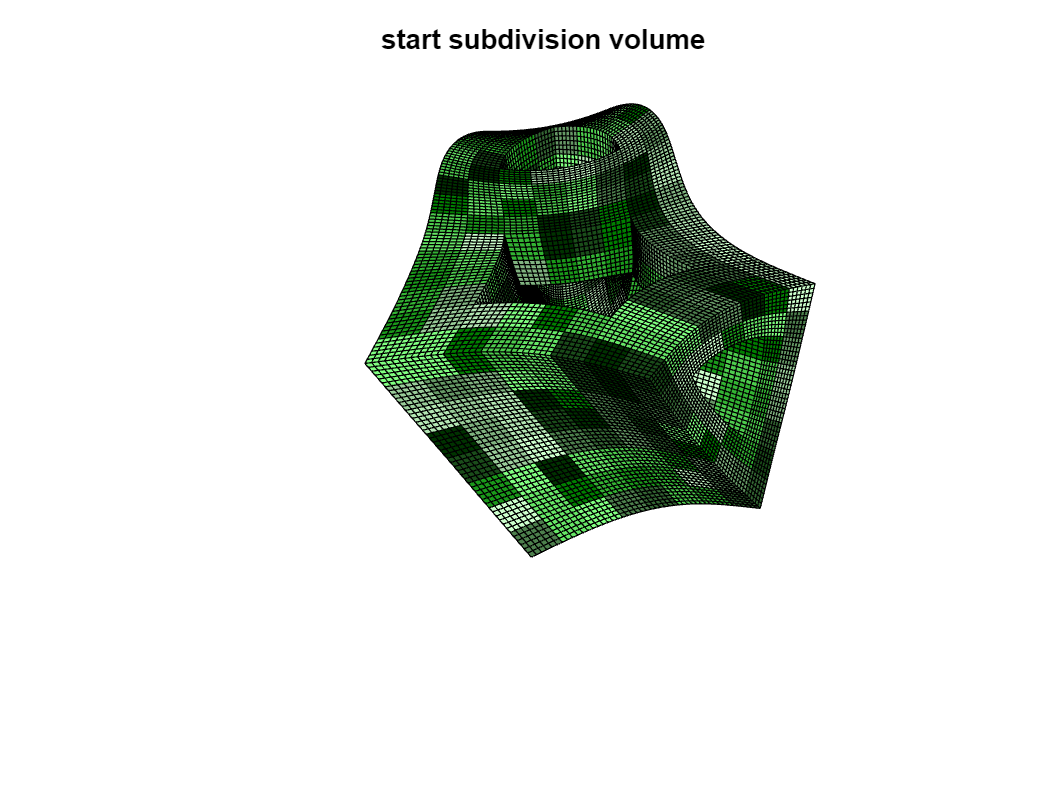

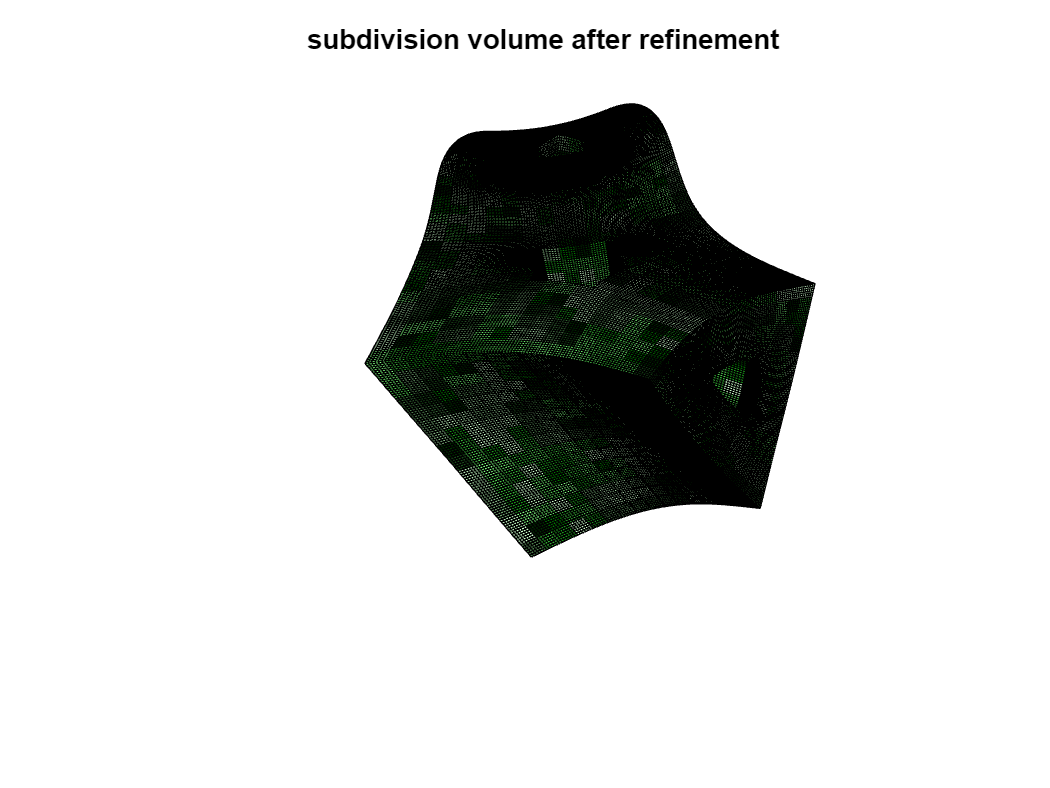

ExampleCubicUniformRefinement